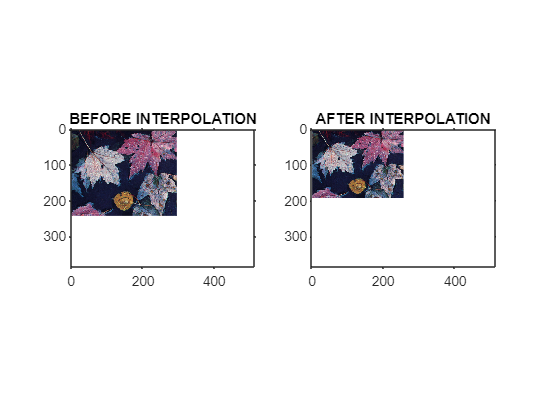

clear all
clc
close all
%READ A RGB IMAGE
A=imread('C:\Users\tvasu\Desktop\leaves.png');


% DEFINE THE RESAMPLE SIZE
Col = 256;
Row = 192;


%FIND THE RATIO OF THE NEW SIZE BY OLD SIZE
rtR = Row/size(A,1);
rtC = Col/size(A,2);

%OBTAIN THE INTERPOLATED POSITIONS
IR = ceil([1:(size(A,1)*rtR)]./(rtR));
IC = ceil([1:(size(A,2)*rtC)]./(rtC));


%RED CHANNEL
Temp= A(:,:,1);
%ROW-WISE INTERPOLATION
Red = Temp(IR,:);
%COLUMNWISE INTERPOLATION
Red = Red(:,IC);



%GREEN CHANNEL
Temp= A(:,:,2);
%ROW-WISE INTERPOLATION
Green = Temp(IR,:);
%COLUMNWISE INTERPOLATION
Green = Green(:,IC);


%BLUE CHANNEL
Temp= A(:,:,3);
%ROW-WISE INTERPOLATION
Blue = Temp(IR,:);
%COLUMNWISE INTERPOLATION
Blue = Blue(:,IC);



Output=zeros([Row,Col,3]);
Output(:,:,1)=Red;
Output(:,:,2)=Green;
Output(:,:,3)=Blue;

Output = uint8(Output);

figure,subplot(121),imshow(A);title('BEFORE INTERPOLATION'); axis([0,512,0,384]);axis on;

subplot(122),imshow(Output);title('AFTER INTERPOLATION');  axis([0,512,0,384]);axis on;